clear
initUtility
importData

T_handle_new_property = readtable('data/processed_behavior/experience_handle_new_property.csv');
T_nullify_you = readtable('data/processed_behavior/experience_nullify_you.csv');
T_pushable_extension = readtable('data/processed_behavior/experience_pushable_extension.csv');
T_superstitious_pushing = readtable('data/processed_behavior/experience_superstitious_pushing.csv');
T_treating_obstacle = readtable('data/processed_behavior/experience_treating_obstacle.csv');

T_handle_new_property(:, 1) = [];
T_nullify_you(:, 1) = [];
T_pushable_extension(:, 1) = [];
T_superstitious_pushing(:, 1) = [];
T_treating_obstacle(:, 1) = [];

full_experience = [T_treating_obstacle, T_superstitious_pushing, T_pushable_extension, T_handle_new_property, T_nullify_you];

clear T_handle_new_property T_nullify_you T_pushable_extension T_superstitious_pushing T_treating_obstacle

% removes behaviors that less than 4 participant perform
count = sum(full_experience{:, :}, 'omitnan');
logicalVector = count < 4;
full_experience(:, logicalVector) = [];

%% add trait
Q = sortrows(Q, 'SubNo');
X = Q{:, surveyLabel};
[~,score,~, ~, ~, ~] = pca(zscore(X));

% save the first 2 components
full_experience = addvars(full_experience, score(:, 1), score(:, 2), 'Before', 1, 'NewVariableNames', {'GameFreq', 'GamePref'});
clear X Q U score



%% correlation

varlabels = full_experience.Properties.VariableNames;
varlabels = replace(varlabels, '_', '\_');
                        
[RHO,PVALUE] = corr(full_experience{:, :}, 'Type', 'Pearson', 'Rows', 'pairwise');
upper_tri = triu(ones(size(PVALUE), 'logical'));



## with fdr correction

PVALUE_lowertri = PVALUE;
PVALUE_lowertri(upper_tri) = nan;
p_list = PVALUE_lowertri(:);
p_list = p_list(p_list > 0); % remove upper triangular values
p_list = sort(p_list);
[~,~,r] = unique(p_list,'sorted'); % ranks from lowest to highest
q = p_list * numel(p_list) ./ r;
q_index = find(q <= 0.05, 1, 'last');
p_bnd = p_list(q_index);
disp(q_index)

    13



## correlation plot

logicalArray = PVALUE <= p_bnd;
var_Sig = sum(logicalArray) > 0;
RHO(~logicalArray) = nan;
RHO(upper_tri) = nan;
PVALUE(upper_tri) = nan;

RHO_subset = RHO(var_Sig, var_Sig);
PVALUE_subset = PVALUE(var_Sig, var_Sig)

PVALUE_subset =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1616       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1168    0.2451       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3663    0.7161    0.3962       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2488    0.3285    0.2638    0.2272       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9605    0.4328    0.0989    0.0000    0.0028       NaN       NaN       NaN       NaN       NaN       NaN       NaN       Na

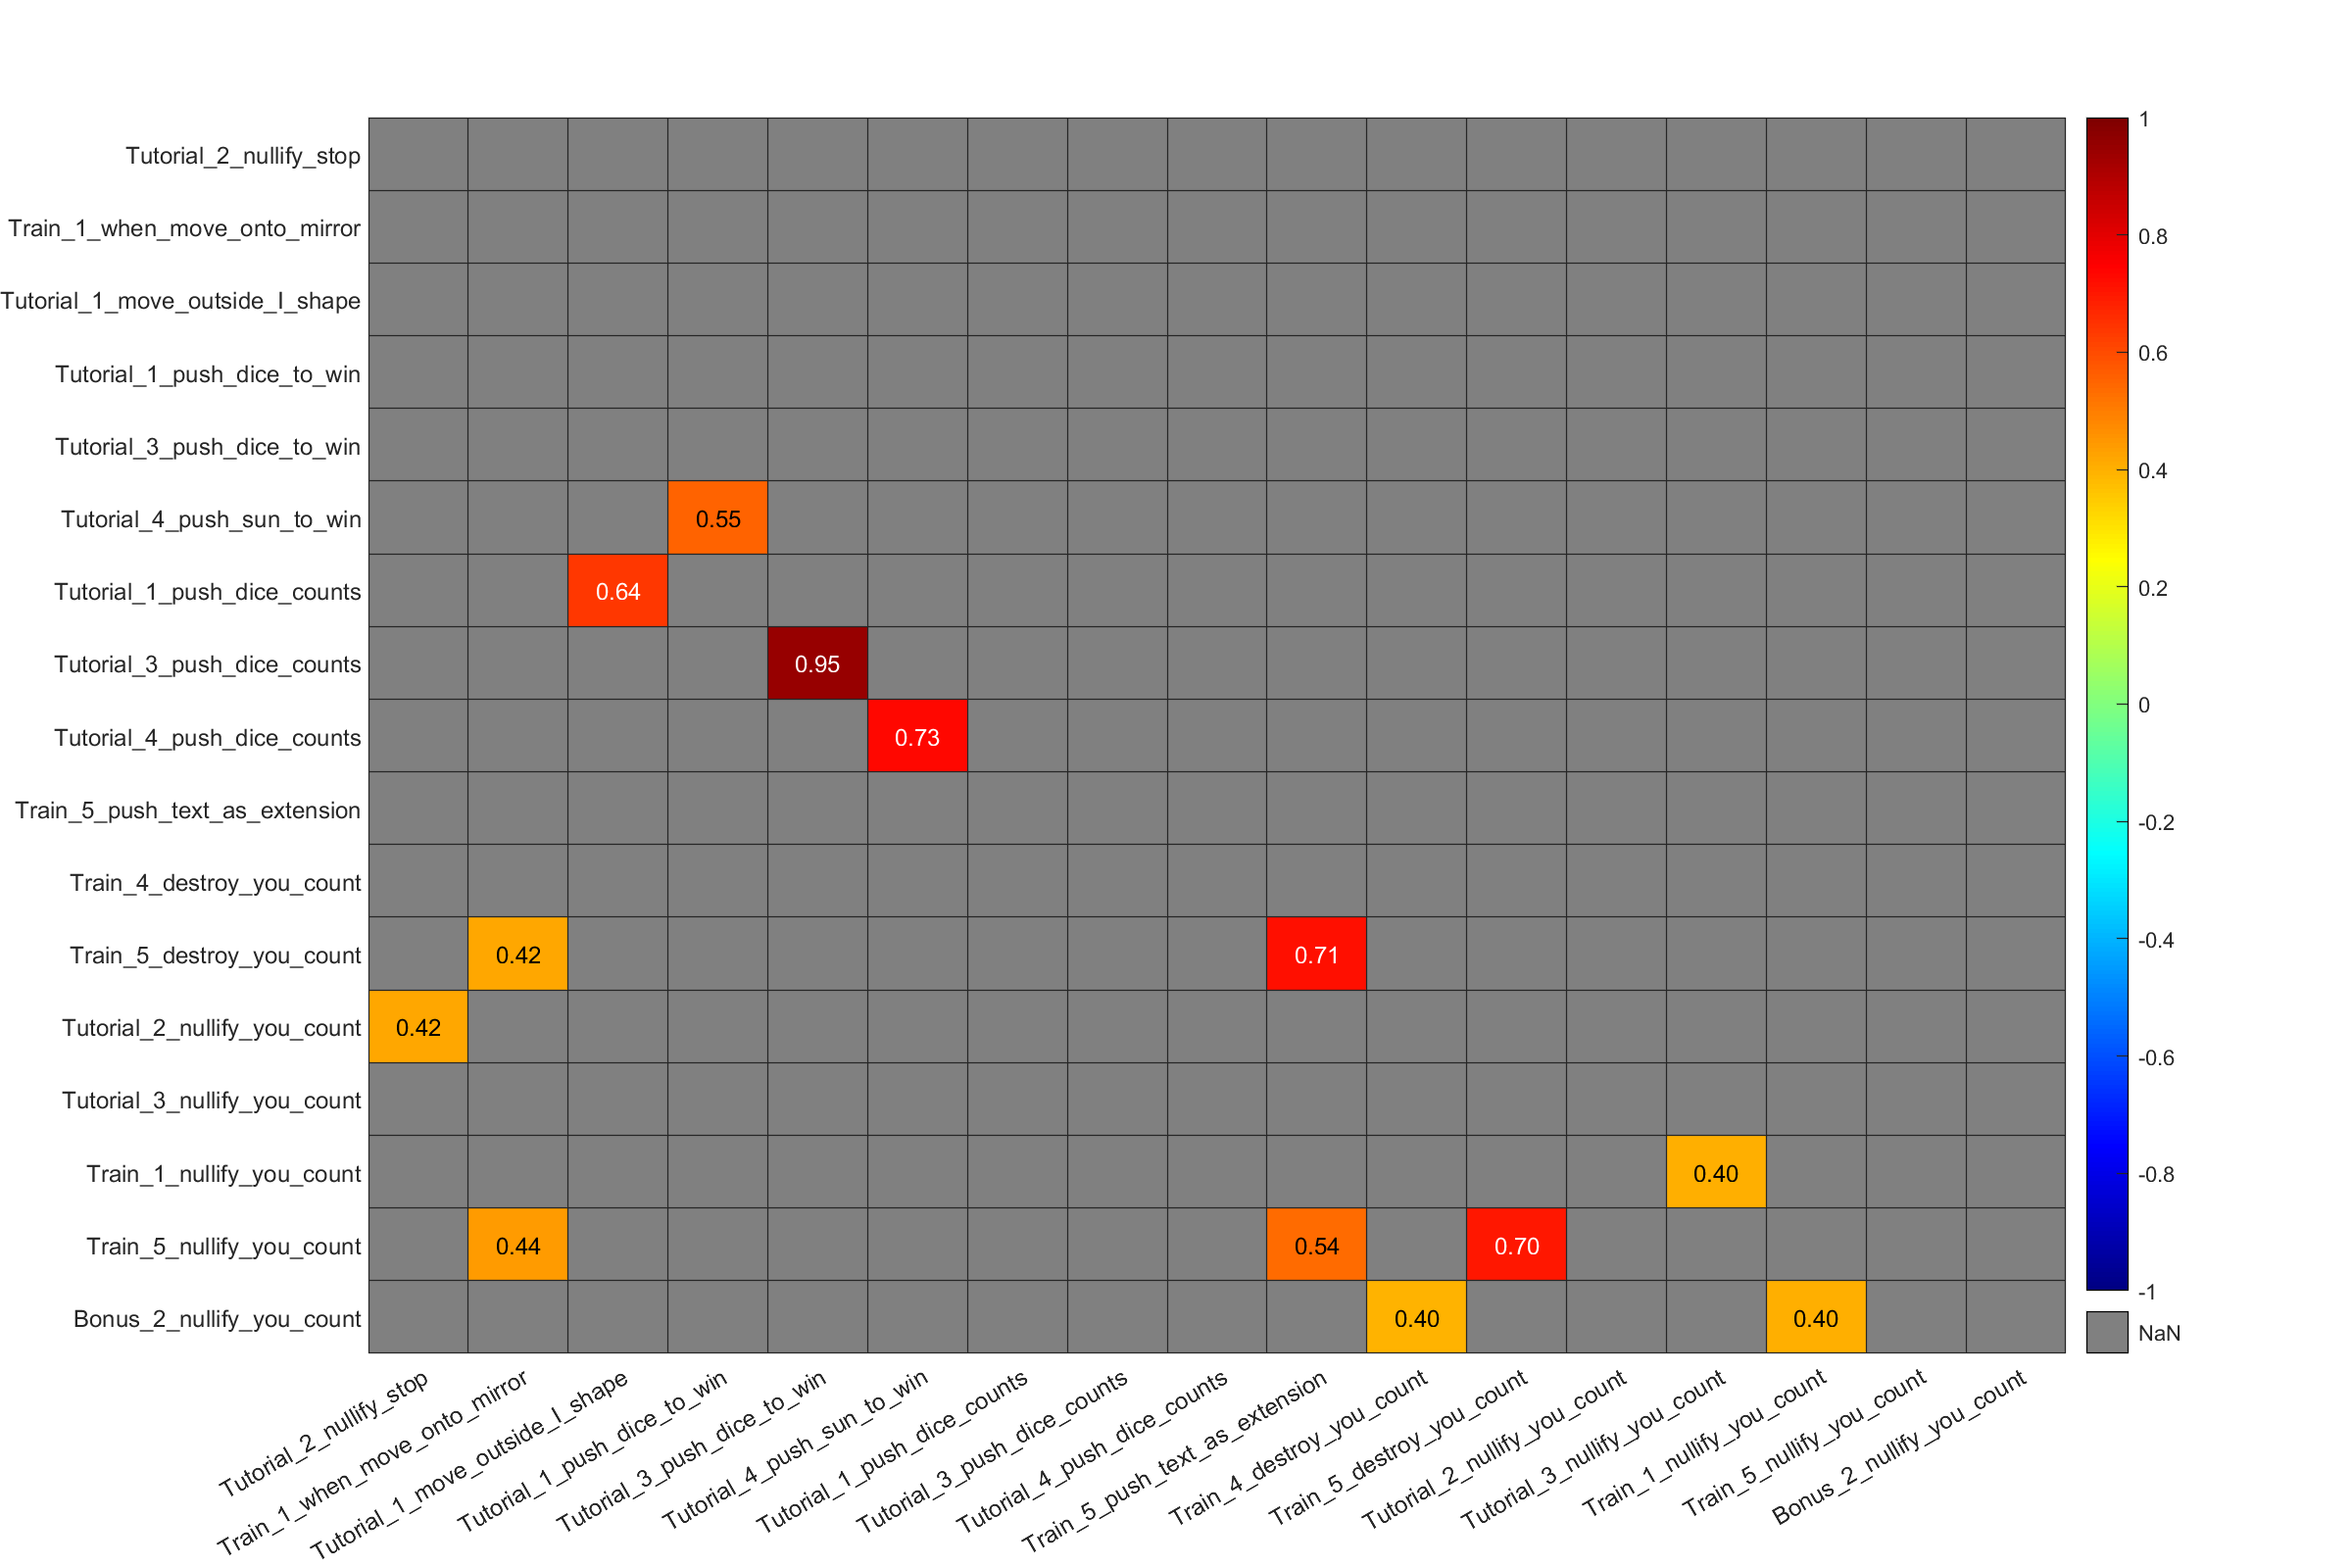

varlabels_subset = varlabels(var_Sig);
figure('Position', [0 0 1200 800]); 
h = heatmap(RHO_subset, 'MissingDataColor',[0.5 0.5 0.5]);
colormap(h, jet);
caxis([-1 1]);
% figure(2); colormap(flip(autumn(256),1))
% hp = heatmap(PVALUE);
% colormap(hp, flip(autumn(256),1));

h.XDisplayLabels = varlabels_subset;
h.YDisplayLabels = varlabels_subset;
h.CellLabelFormat = '%.2f';
h.FontSize = 9;